## **Taller: métodos no paramétricos de identificación**

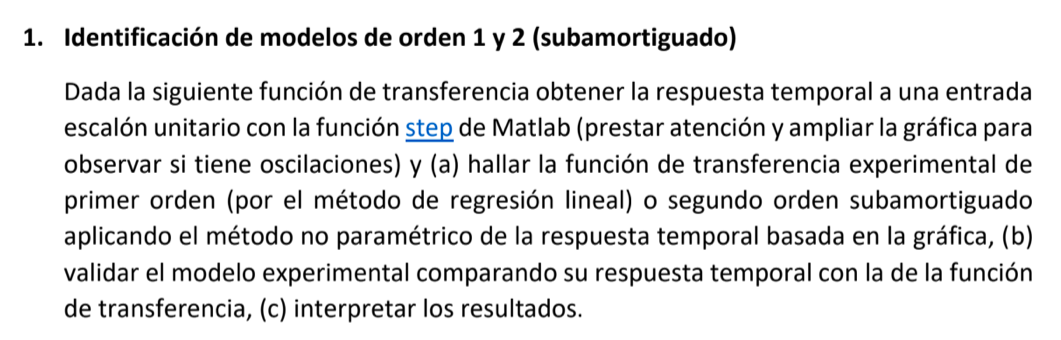

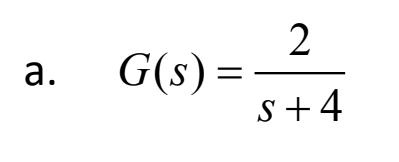

%función de transferencia
G1 = tf(2,[1 4])

G1 =
 
    2
  -----
  s + 4
 
Continuous-time transfer function.



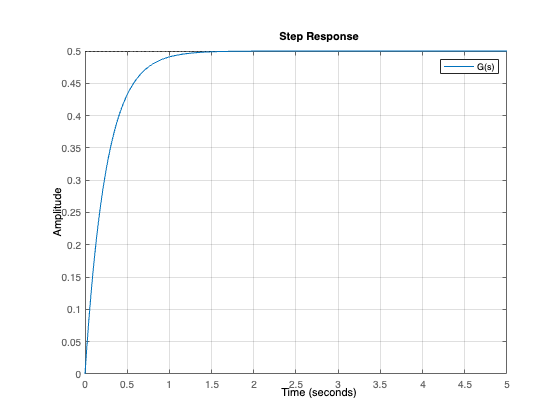

%respuesta temporal a una entrada de escalón unitario
tiempofinal = 5;
figure(1)
clf
step(G1,tiempofinal)
grid on
legend({'G(s)'})

[y,t] = step(G1,tiempofinal);
inicio = find(y > 0, 1);%identificamos el dato a partir del cual el modelo responde a la entrada
yvalores = y(inicio:end);
tvalores = t(inicio:end);
k = yvalores(end)-y(1); %valor de k según la fórmula

*a) Método de regresión lineal*

[p,s] = polyfit(tvalores,log(1-yvalores/(k+eps)),1);%regresión lineal al logaritmo de y
T = -1/p(1);
tau = -p(2)/p(1);%valores de parámetros  T y tau según las fórmulas
tfEstimada = tf(k,[T 1],'InputDelay',tau)%función de transferencia resultante

tfEstimada =
 
                       0.5
  exp(-0.0645*s) * ------------
                   0.2402 s + 1
 
Continuous-time transfer function.



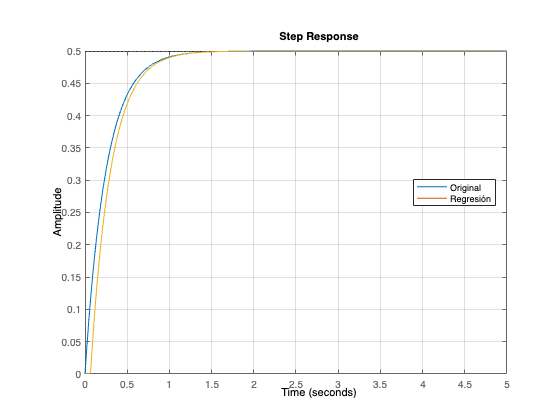

figure(1)
hold on
step(tfEstimada)
legend({'Original','Regresión'},'Location','best')

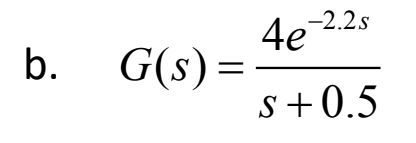

%función de transferencia
G2 = zpk([],[-0.5],4,'InputDelay',2.2)

G2 =
 
                   4
  exp(-2.2*s) * -------
                (s+0.5)
 
Continuous-time zero/pole/gain model.



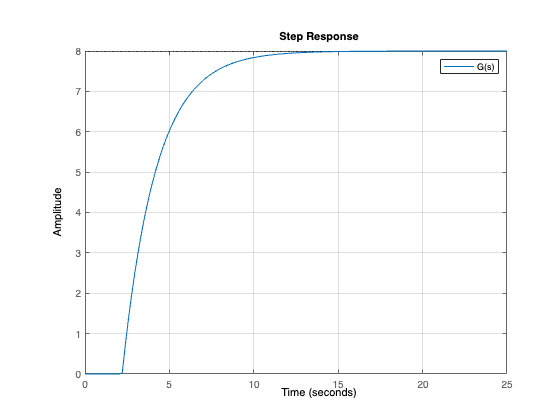

%respuesta temporal a una entrada de escalón unitario
tiempofinal = 25;
figure(2)
clf
step(G2,tiempofinal)
grid on
legend({'G(s)'})

[y,t] = step(G2,tiempofinal)

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


t =          0
    0.1838
    0.3676
    0.5515
    0.7353
    0.9191
    1.1029
    1.2868
    1.4706
    1.6544


inicio = find(y > 0, 1)%identificamos el dato a partir del cual el modelo responde a la entrada

inicio = 13

yvalores = y(inicio:end)

yvalores =     0.0235
    0.7239
    1.3629
    1.9457
    2.4774
    2.9623
    3.4047
    3.8083
    4.1763
    4.5121


tvalores = t(inicio:end)

tvalores =     2.2059
    2.3897
    2.5735
    2.7574
    2.9412
    3.1250
    3.3088
    3.4926
    3.6765
    3.8603


k = yvalores(end)-y(1) %valor de k según la fórmula

k = 7.9999

*a) Método de regresión lineal*

[p,s] = polyfit(tvalores,log(1-yvalores/(k+eps)),1)%regresión lineal al logaritmo de y

p =    NaN   NaN


s = struct with fields:
        R: [2×2 double]
       df: 123
    normr: NaN


T = -1/p(1)

T = NaN

tau = -p(2)/p(1)%valores de parámetros  T y tau según las fórmulas

tau = NaN

tfEstimada = tf(k,[T 1],'InputDelay',tau)%función de transferencia resultante

Error using tf
The "InputDelay" property must be set to a vector of real finite numbers.

figure(2)
hold on
step(tfEstimada)
legend({'Original','Regresión'},'Location','best')


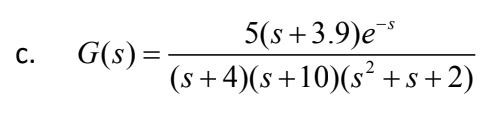

syms s
f1 = s^2+s+2;
factor(f1, 'FactorMode', 'complex')

$$ans = \left(\begin{array}{cc} s+0.5+1.3228756555322952952508078768196\,\mathrm{i} & s+0.5-1.3228756555322952952508078768196\,\mathrm{i} \end{array}\right)$$

%función de transferencia
G3 = zpk([-3.9],[-4, -10, -(0.5 + 1.32287*i),-( 0.5-1.32287*i)],5,'InputDelay',1)

G3 =
 
                      5 (s+3.9)
  exp(-1*s) * --------------------------
              (s+4) (s+10) (s^2 + s + 2)
 
Continuous-time zero/pole/gain model.



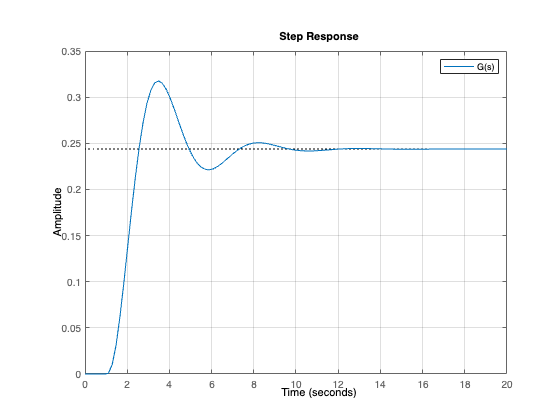

%respuesta temporal a una entrada de escalón unitario
tiempofinal = 20;
figure(3)
clf
step(G3,tiempofinal)
grid on
legend({'G(s)'})

[y,t] = step(G3);%recolección de datos por recomendación de MatLab
inicio = find(y > 0, 1);%dato a partir del cual el sistema reacciona
tau = t(inicio)%tiempo a partir del cual el sistema reacciona

tau = 1.0131

deltaY = y(end) - y(1)%delta de y por definición

deltaY = 0.2430

Mp = max(y) - y(end);%sobreimpulso máximo pode definición
Tp = t(y == max(y)) - tau;%tiempo de pico, se le debe restar el retardo
%zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)
zeta = -log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)

zeta = 0.6371

omega0 = pi/(Tp*sqrt(1-zeta^2))%valor de omega0 por fórmulas

omega0 = 1.6389

tfEstimada=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tfEstimada =
 
                        0.6527
  exp(-1.01*s) * ---------------------
                 s^2 + 2.088 s + 2.686
 
Continuous-time transfer function.



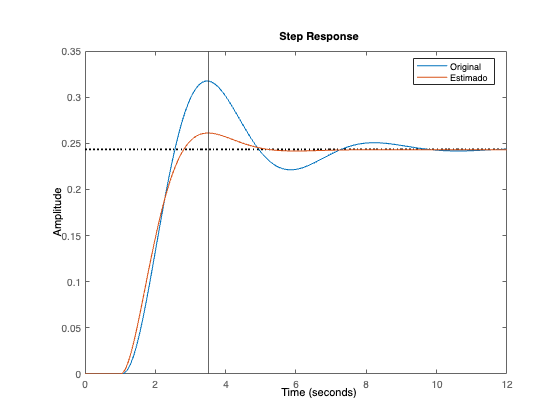

figure(3)
clf
step(G3)
hold on
step(tfEstimada)
xline(Tp+tau)
legend({'Original','Estimado'},'Location','best')

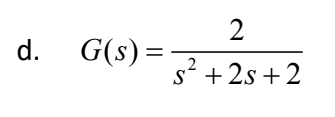

syms s
f1 = s^2+2*s+2;
factor(f1, 'FactorMode', 'complex')

$$ans = \left(\begin{array}{cc} s+1.0+1.0\,\mathrm{i} & s+1.0-1.0\,\mathrm{i} \end{array}\right)$$

%función de transferencia
G4 = zpk([ ],[-(1 + 1*i),-( 1-1*i)],2)

G4 =
 
        2
  --------------
  (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.



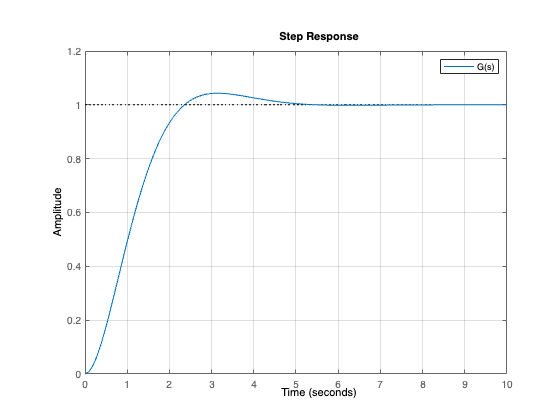

%respuesta temporal a una entrada de escalón unitario
tiempofinal = 10;
figure(4)
clf
step(G4,tiempofinal)
grid on
legend({'G(s)'})

[y,t] = step(G4);%recolección de datos por recomendación de MatLab
inicio = find(y > 0, 1);%dato a partir del cual el sistema reacciona
tau = t(inicio)%tiempo a partir del cual el sistema reacciona

tau = 0.0461

deltaY = y(end) - y(1)%delta de y por definición

deltaY = 0.9981

Mp = max(y) - y(end);%sobreimpulso máximo pode definición
Tp = t(y == max(y)) - tau;%tiempo de pico, se le debe restar el retardo
%zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)
zeta = -log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)

zeta = 0.7023

omega0 = pi/(Tp*sqrt(1-zeta^2))%valor de omega0 por fórmulas

omega0 = 1.4303

tfEstimada=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tfEstimada =
 
                           2.042
  exp(-0.0461*s) * ---------------------
                   s^2 + 2.009 s + 2.046
 
Continuous-time transfer function.



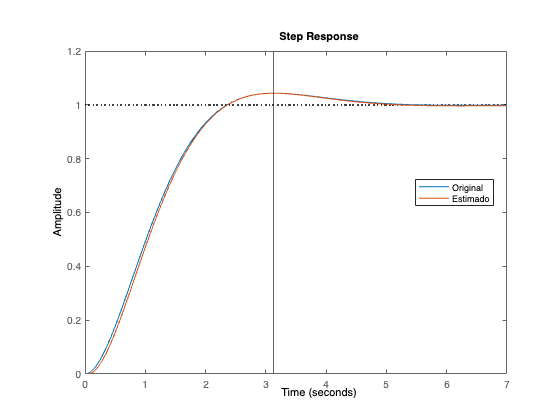

figure(4)
clf
step(G4)
hold on
step(tfEstimada)
xline(Tp+tau)
legend({'Original','Estimado'},'Location','best')

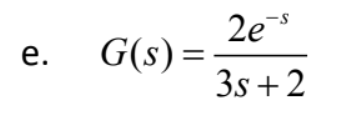


syms s
f1 = 3*s+2;
factor(f1, 'FactorMode', 'complex')

$$ans = \left(\begin{array}{cc} 3.0 & s+0.66666666666666666666666666666667 \end{array}\right)$$

%función de transferencia
G5 = zpk([ ],[-0.66666],(2*1/3),'InputDelay',1)

G5 =
 
               0.66667
  exp(-1*s) * ----------
              (s+0.6667)
 
Continuous-time zero/pole/gain model.



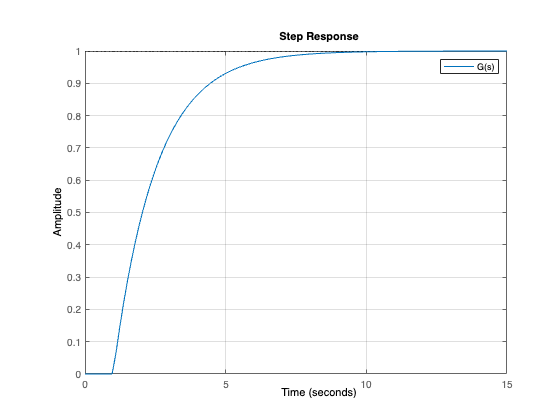

%respuesta temporal a una entrada de escalón unitario
tiempofinal = 15;
figure(5)
clf
step(G5,tiempofinal)
grid on
legend({'G(s)'})